clear all
syms lambda rA rB R1 R2 R3 uA3 uB3 ;


r1=[2.626;6.924;24.665];
u31=[0.2917;-0.9562;-0.0221];
r2=[2.440;11.449;17.249];
u32=[0.3005;0.9534;-0.025];
r3=[7.518;0.711;21.079];
u33=[-0.2917;-0.9562;0.0221];
r4=[7.704;5.236;28.495];
u34=[-0.3005;0.9534;0.025];
r5=[2.632;0.977;32.497];
u35=[-0.3005;-0.9534;-0.025];


x1=[];
y1=[];
x2=[];
y2=[];
x3=[];
y3=[];
x4=[];
y4=[];
x5=[];
y5=[];
x6=[];
y6=[];

hold on 
axis([0 15 0 15]);


for R3=3:0.3:10 %离心率
    R1=2;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r4,R1,R3,u31,u34);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r4,R1,R3,u31,u34);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r4,R1,R3,u31,u34);
    end
    [R1,R3,miu2]
    x3=[x3,R1];
    y3=[y3,R3];   
end

ans =     3.3500    3.0000    1.0150


ans =     3.2500    3.3000    1.0184


ans =     3.2000    3.6000    1.0103


ans =     3.1500    3.9000    1.0109


ans =     3.1000    4.2000    1.0182


ans =     3.1000    4.5000    1.0014


ans =     3.0500    4.8000    1.0171


ans =     3.0500    5.1000    1.0058


ans =     3.0000    5.4000    1.0271


ans =     3.0000    5.7000    1.0191


ans =     3.0000    6.0000    1.0122


ans =     3.0000    6.3000    1.0063


ans =     3.0000    6.6000    1.0012


ans =     2.9500    6.9000    1.0291


ans =     2.9500    7.2000    1.0252


ans =     2.9500    7.5000    1.0218


ans =     2.9500    7.8000    1.0187


ans =     2.9500    8.1000    1.0159


ans =     2.9500    8.4000    1.0135


ans =     2.9500    8.7000    1.0113


ans =     2.9500    9.0000    1.0093


ans =     2.9500    9.3000    1.0075


ans =     2.9500    9.6000    1.0059


ans =     2.9500    9.9000    1.0044



for R3=3:0.3:10 %离心率
    R1=3;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r5,R1,R3,u31,u35);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r5,R1,R3,u31,u35);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r5,R1,R3,u31,u35);
    end
    [R1,R3,miu2]
    x4=[x4,R1];
    y4=[y4,R3];   
end

ans =     6.9000    3.0000    1.0018


ans =     6.3500    3.3000    1.0084


ans =     5.9500    3.6000    1.0033


ans =     5.6000    3.9000    1.0046


ans =     5.3500    4.2000    1.0003


ans =     5.1000    4.5000    1.0100


ans =     4.9500    4.8000    1.0061


ans =     4.8000    5.1000    1.0116


ans =     4.7000    5.4000    1.0099


ans =     4.6000    5.7000    1.0143


ans =     4.5500    6.0000    1.0069


ans =     4.5000    6.3000    1.0032


ans =     4.4500    6.6000    1.0026


ans =     4.4000    6.9000    1.0048


ans =     4.3500    7.2000    1.0095


ans =     4.3000    7.5000    1.0165


ans =     4.3000    7.8000    1.0050


ans =     4.2500    8.1000    1.0152


ans =     4.2500    8.4000    1.0060


ans =     4.2000    8.7000    1.0188


ans =     4.2000    9.0000    1.0113


ans =     4.2000    9.3000    1.0045


ans =     4.1500    9.6000    1.0202


ans =     4.1500    9.9000    1.0145


for R1=5:0.3:8 %离心率
    R3=3;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r2,R1,R3,u31,u32);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    [R1,R3,miu2]
    x1=[x1,R1];
    y1=[y1,R3];   
end

ans =     5.0000    3.1500    1.0064


ans =     5.3000    2.8500    1.0093


ans = 1×3
    5.6000    2.6000    1.0139


ans = 1×3
    5.9000    2.4000    1.0125


ans = 1×3
    6.2000    2.2000    1.0164


ans = 1×3
    6.5000    2.0500    1.0055


ans = 1×3
    6.8000    1.8500    1.0115


ans = 1×3
    7.1000    1.6500    1.0148


ans = 1×3
    7.4000    1.4500    1.0132


ans = 1×3
    7.7000    1.2500    1.0048


ans = 1×3
    8.0000    0.9500    1.0103



for R3=3:0.3:9 %离心率
    R1=3;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r2,R1,R3,u31,u32);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    [R1,R3,miu2]
    x1=[x1,R1];
    y1=[y1,R3];   
end

ans = 1×3
    5.1500    3.0000    1.0055


ans = 1×3
    4.8500    3.3000    1.0123


ans = 1×3
    4.6500    3.6000    1.0099


ans = 1×3
    4.5000    3.9000    1.0068


ans = 1×3
    4.3500    4.2000    1.0155


ans = 1×3
    4.2500    4.5000    1.0168


ans = 1×3
    4.2000    4.8000    1.0065


ans = 1×3
    4.1500    5.1000    1.0012


ans = 1×3
    4.1000    5.4000    1.0001


ans = 1×3
    4.0500    5.7000    1.0027


ans = 1×3
    4.0000    6.0000    1.0084


ans = 1×3
    3.9500    6.3000    1.0169


ans = 1×3
    3.9500    6.6000    1.0051


ans = 1×3
    3.9000    6.9000    1.0176


ans = 1×3
    3.9000    7.2000    1.0084


ans = 1×3
    3.9000    7.5000    1.0003


ans = 1×3
    3.8500    7.8000    1.0167


ans = 1×3
    3.8500    8.1000    1.0102


ans = 1×3
    3.8500    8.4000    1.0044


ans = 1×3
    3.8000    8.7000    1.0237


ans = 1×3
    3.8000    9.0000    1.0189




for R3=2:0.3:10 %离心率
    R1=3;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r3,R1,R3,u31,u33);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r3,R1,R3,u31,u33);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r3,R1,R3,u31,u33);
    end
    [R1,R3,miu2]
    x2=[x2,R1];
    y2=[y2,R3];   
end

ans = 1×3
    9.7500    2.0000    1.0061


ans = 1×3
    9.0000    2.3000    1.0062


ans = 1×3
    8.2000    2.6000    1.0027


ans = 1×3
    7.3000    2.9000    1.0046


ans = 1×3
    6.4500    3.2000    1.0008


ans = 1×3
    5.6500    3.5000    1.0037


ans = 1×3
    5.0500    3.8000    1.0022


ans = 1×3
    4.6000    4.1000    1.0027


ans = 1×3
    4.2500    4.4000    1.0084


ans = 1×3
    4.0000    4.7000    1.0107


ans = 1×3
    3.8000    5.0000    1.0145


ans = 1×3
    3.6500    5.3000    1.0143


ans = 1×3
    3.5500    5.6000    1.0050


ans = 1×3
    3.4500    5.9000    1.0013


ans = 1×3
    3.3500    6.2000    1.0021


ans = 1×3
    3.2500    6.5000    1.0068


ans = 1×3
    3.1500    6.8000    1.0147


ans = 1×3
    3.1000    7.1000    1.0044


ans = 1×3
    3.0000    7.4000    1.0169


ans = 1×3
    2.9500    7.7000    1.0095


ans = 1×3
    2.9000    8.0000    1.0032


ans = 1×3
    2.8000    8.3000    1.0203


ans = 1×3
    2.7500    8.6000    1.0161


ans = 1×3
    2.7000    8.9000    1.0127


ans = 1×3
    2.6500    9.2000    1.0102


ans = 1×3
    2.6000    9.5000    1.0086


ans = 1×3
    2.5500    9.8000    1.0078


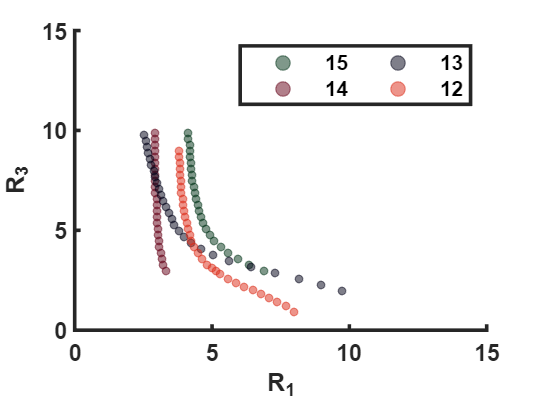





scatter(x4,y4,10,'markerfacecolor',[0, 50, 22]/256,...
        'markeredgecolor',[0, 50, 22]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','15')
scatter(x3,y3,10,'markerfacecolor',[100, 0, 22]/256,...
        'markeredgecolor',[100, 0, 22]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','14')

scatter(x2,y2,10,'markerfacecolor',[0, 0, 22]/256,...
        'markeredgecolor',[0, 0, 22]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','13')

scatter(x1,y1,10,'markerfacecolor',[221, 42, 22]/256,...
        'markeredgecolor',[221, 42, 22]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','12')







set(gca,'linewidth',1.5,'FontWeight','bold','FontName','arial');
xlabel('R_1','FontName','arial','FontWeight','bold'); 
ylabel('R_3','FontName','arial','FontWeight','bold');
legend('Location','northeast','NumColumns',2);
hold off

function miu2=cont(rA,rB,R1,R3,uA3,uB3)
    syms lambda
    rAB=rB-rA;
    e=R3/R1;
    x=(1-lambda)*(1-e^2);
    y=lambda*(1-e^2);
    D=(1-x)*(1-y)-x*y*(dot(uA3,uB3))^2;
    alpha=x*(1-y)/D;
    beta=y*(1-x)/D;
    gama=x*y*(dot(uA3,uB3))/D;
    I=eye(3);
    C=(I+alpha*(uA3*uA3.')+beta*(uB3*uB3.')+gama*((uA3*uB3.')+(uB3*uA3.')))/(R1^2);
    F=lambda*(1-lambda)*(rAB.'*C*rAB);
    fun=@(lambda) -eval(F);
    [~,fval]=fminbnd(fun,0,1);
    miu2=-fval;
end

